# Estimate AprilTag Poses in Image

Read an image that contains AprilTags into the workspace. Display the image.

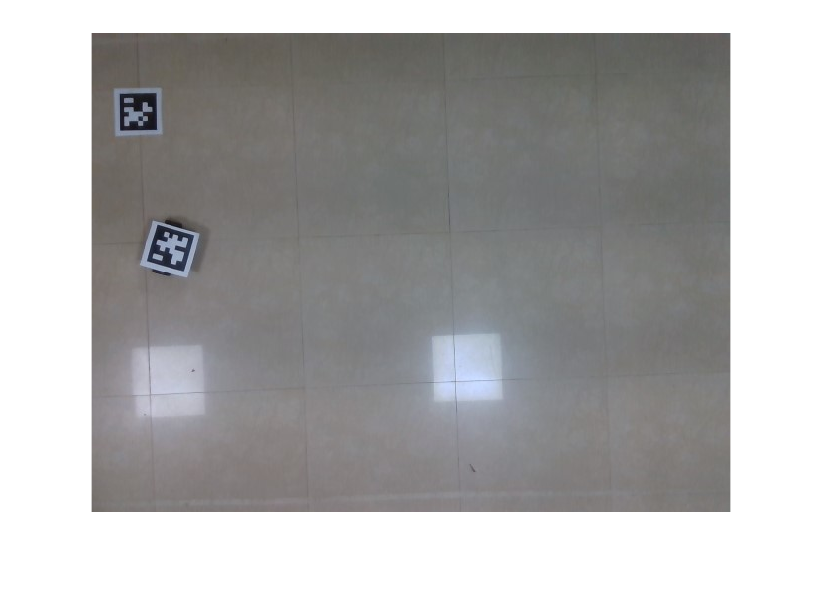

I = imread("C:\Users\anujt\OneDrive\Documents\MATLAB\Skandhan\WIN_20241013_20_32_27_Pro.jpg");
imshow(I)

Load the camera intrinsic parameters.

% data = load("camIntrinsicsAprilTag.mat");
intrinsics = Intrinsics;  

Specify the tag size in meters.

tagSize = 0.141;

Undistort the input image using the camera intrinsic parameters.

I = undistortImage(I,intrinsics,OutputView="same");

Detect a specific family of AprilTags and estimate the tag poses.

[id,loc,pose] = readAprilTag(I,"tag36h11",intrinsics,tagSize);

Set the origin for the axes vectors  and for the tag frames.

worldPoints = [0 0 0; tagSize/2 0 0; 0 tagSize/2 0; 0 0 tagSize/2];

Add the tag frames and IDs to the image.

for i = 1:length(pose)
    % Get image coordinates for axes.
    imagePoints = world2img(worldPoints,pose(i),intrinsics);

    % Draw colored axes.
    I = insertShape(I,Line=[imagePoints(1,:) imagePoints(2,:); ...
        imagePoints(1,:) imagePoints(3,:); imagePoints(1,:) imagePoints(4,:)], ...
        ShapeColor=["red","green","blue"],LineWidth=7);

    I = insertText(I,loc(1,:,i),id(i),BoxOpacity=1,FontSize=25);
end

Display the annotated image.

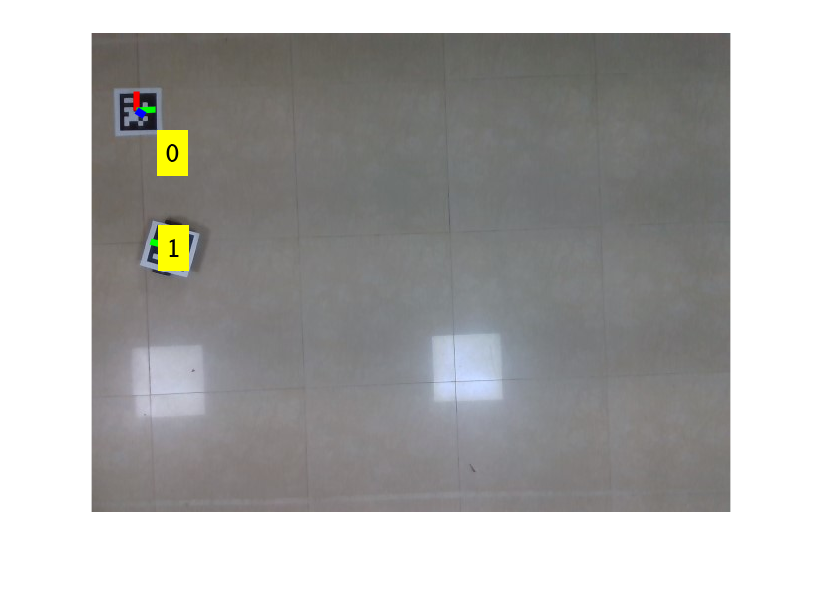

imshow(I)

*Copyright 2020 The MathWorks, Inc.*